Nicolo Mega

EECE4512

Semester Project

Data Processing - EDG

close all 
clear vars 
clc
sampl_rate = 1000;
n_order = 5;
f_c = 5;

Import Daves Data Test 1 (D1)

%Morning Refresh
D1R=readmatrix('Eric ECG and EDA Day 1 Morning.txt');
EDAD1R = D1R(:,8); %desired eda output A2
TD1R = 1:length(D1R);
TD1R = TD1R/1000;

A = [TD1R', EDAD1R(:,1)];
writematrix(A,'test1.txt','Delimiter',' ');
type test1.txt

0.001 165
0.002 166
0.003 165
0.004 166
0.005 165
0.006 166
0.007 165
0.008 166
0.009 166
0.01 166
0.011 166
0.012 165
0.013 166
0.014 165
0.015 166
0.016 166
0.017 165
0.018 166
0.019 165
0.02 166
0.021 165
0.022 166
0.023 166
0.024 166
0.025 166
0.026 166
0.027 166
0.028 166
0.029 166
0.03 165
0.031 166
0.032 165
0.033 166
0.034 165
0.035 166
0.036 166
0.037 164
0.038 166
0.039 165
0.04 166
0.041 166
0.042 165
0.043 166
0.044 166
0.045 165
0.046 166
0.047 166
0.048 165
0.049 166
0.05 164
0.051 166
0.052 164
0.053 166
0.054 165
0.055 165
0.056 165
0.057 164
0.058 166
0.059 164
0.06 165
0.061 164
0.062 166
0.063 165
0.064 165
0.065 165
0.066 164
0.067 165
0.068 164
0.069 166
0.07 165
0.071 164
0.072 165
0.073 164
0.074 166
0.075 165
0.076 164
0.077 166
0.078 164
0.079 166
0.08 166
0.081 165
0.082 164
0.083 165
0.084 164
0.085 165
0.086 164
0.087 166
0.088 165
0.089 165
0.09 165
0.091 165
0.092 165
0.093 164
0.094 165
0.095 164
0.096 165
0.097 164
0.098 165
0.099 165
0.1 165
0.101 164
0

%Time = 0
D10=readmatrix('Eric Day 1 before Test.txt');
EDAD10 = D10(:,8); %desired eda output A2
TD10 = 1:length(D10);
TD10 = TD10/1000;

A = [TD10', EDAD10(:,1)];
writematrix(A,'test2.txt','Delimiter',' ');
type test2.txt

0.001 164
0.002 164
0.003 164
0.004 164
0.005 164
0.006 164
0.007 164
0.008 163
0.009 163
0.01 163
0.011 163
0.012 163
0.013 163
0.014 163
0.015 163
0.016 163
0.017 163
0.018 164
0.019 163
0.02 163
0.021 164
0.022 164
0.023 164
0.024 163
0.025 163
0.026 163
0.027 163
0.028 163
0.029 163
0.03 163
0.031 164
0.032 163
0.033 163
0.034 163
0.035 164
0.036 164
0.037 164
0.038 164
0.039 164
0.04 164
0.041 164
0.042 164
0.043 164
0.044 164
0.045 164
0.046 164
0.047 164
0.048 164
0.049 164
0.05 164
0.051 164
0.052 164
0.053 164
0.054 164
0.055 164
0.056 164
0.057 164
0.058 164
0.059 164
0.06 163
0.061 163
0.062 163
0.063 164
0.064 164
0.065 164
0.066 164
0.067 164
0.068 164
0.069 164
0.07 164
0.071 164
0.072 165
0.073 164
0.074 164
0.075 164
0.076 164
0.077 163
0.078 163
0.079 163
0.08 163
0.081 163
0.082 163
0.083 163
0.084 164
0.085 164
0.086 164
0.087 164
0.088 164
0.089 164
0.09 164
0.091 164
0.092 163
0.093 163
0.094 163
0.095 163
0.096 163
0.097 163
0.098 163
0.099 163
0.1 163
0.101 164
0

%Time = 10
D11=readmatrix('Eric Day 1 Test 1.txt');
EDAD11 = D11(:,8); %desired eda output A2
TD11 = 1:length(D11);
TD11 = TD11/1000;

A = [TD11', EDAD11(:,1)];
writematrix(A,'test3.txt','Delimiter',' ');
type test3.txt

0.001 182
0.002 182
0.003 182
0.004 182
0.005 181
0.006 181
0.007 181
0.008 182
0.009 181
0.01 181
0.011 182
0.012 182
0.013 181
0.014 181
0.015 182
0.016 182
0.017 181
0.018 182
0.019 182
0.02 182
0.021 181
0.022 182
0.023 181
0.024 182
0.025 181
0.026 181
0.027 182
0.028 182
0.029 181
0.03 181
0.031 182
0.032 182
0.033 181
0.034 181
0.035 182
0.036 182
0.037 181
0.038 182
0.039 182
0.04 181
0.041 181
0.042 181
0.043 182
0.044 181
0.045 181
0.046 182
0.047 182
0.048 181
0.049 182
0.05 182
0.051 181
0.052 182
0.053 182
0.054 181
0.055 181
0.056 182
0.057 181
0.058 181
0.059 180
0.06 182
0.061 182
0.062 182
0.063 181
0.064 182
0.065 182
0.066 182
0.067 181
0.068 182
0.069 182
0.07 181
0.071 181
0.072 182
0.073 181
0.074 181
0.075 181
0.076 182
0.077 181
0.078 181
0.079 182
0.08 181
0.081 181
0.082 182
0.083 182
0.084 182
0.085 181
0.086 182
0.087 181
0.088 181
0.089 181
0.09 181
0.091 181
0.092 180
0.093 182
0.094 181
0.095 181
0.096 181
0.097 181
0.098 182
0.099 182
0.1 181
0.101 181
0

%Time = 20
D12=readmatrix('eric day 1 test 2.txt');
EDAD12 = D12(:,8); %desired eda output A2
TD12 = 1:length(D12);
TD12 = TD12/1000;

A = [TD12', EDAD12(:,1)];
writematrix(A,'test4.txt','Delimiter',' ');
type test4.txt

0.001 178
0.002 178
0.003 178
0.004 178
0.005 177
0.006 177
0.007 178
0.008 178
0.009 178
0.01 178
0.011 178
0.012 177
0.013 177
0.014 177
0.015 177
0.016 178
0.017 178
0.018 178
0.019 178
0.02 178
0.021 177
0.022 177
0.023 177
0.024 177
0.025 178
0.026 178
0.027 178
0.028 178
0.029 178
0.03 177
0.031 177
0.032 177
0.033 177
0.034 178
0.035 178
0.036 178
0.037 178
0.038 178
0.039 178
0.04 177
0.041 177
0.042 178
0.043 178
0.044 178
0.045 178
0.046 178
0.047 177
0.048 177
0.049 177
0.05 177
0.051 177
0.052 177
0.053 177
0.054 178
0.055 178
0.056 178
0.057 178
0.058 178
0.059 178
0.06 178
0.061 177
0.062 177
0.063 177
0.064 178
0.065 178
0.066 178
0.067 178
0.068 178
0.069 178
0.07 178
0.071 178
0.072 178
0.073 177
0.074 177
0.075 177
0.076 177
0.077 177
0.078 177
0.079 177
0.08 178
0.081 178
0.082 178
0.083 178
0.084 178
0.085 178
0.086 178
0.087 178
0.088 177
0.089 178
0.09 178
0.091 178
0.092 178
0.093 178
0.094 177
0.095 177
0.096 177
0.097 177
0.098 177
0.099 178
0.1 178
0.101 178
0

%Time = 30
D13=readmatrix('eric day 1 test 3.txt');
EDAD13 = D13(:,8); %desired eda output A2
TD13 = 1:length(D13);
TD13 = TD13/1000;

A = [TD13', EDAD13(:,1)];
writematrix(A,'test5.txt','Delimiter',' ');
type test5.txt

0.001 252
0.002 252
0.003 253
0.004 253
0.005 252
0.006 253
0.007 253
0.008 253
0.009 252
0.01 253
0.011 254
0.012 252
0.013 252
0.014 253
0.015 253
0.016 252
0.017 253
0.018 253
0.019 253
0.02 252
0.021 253
0.022 253
0.023 253
0.024 252
0.025 253
0.026 253
0.027 252
0.028 252
0.029 253
0.03 253
0.031 252
0.032 252
0.033 253
0.034 254
0.035 252
0.036 253
0.037 253
0.038 253
0.039 252
0.04 253
0.041 253
0.042 252
0.043 252
0.044 253
0.045 253
0.046 252
0.047 253
0.048 253
0.049 254
0.05 252
0.051 252
0.052 253
0.053 254
0.054 252
0.055 253
0.056 253
0.057 252
0.058 253
0.059 253
0.06 253
0.061 252
0.062 253
0.063 253
0.064 253
0.065 252
0.066 252
0.067 253
0.068 253
0.069 253
0.07 252
0.071 253
0.072 253
0.073 252
0.074 253
0.075 253
0.076 252
0.077 252
0.078 253
0.079 254
0.08 252
0.081 253
0.082 253
0.083 252
0.084 253
0.085 253
0.086 253
0.087 253
0.088 252
0.089 253
0.09 253
0.091 253
0.092 252
0.093 253
0.094 253
0.095 252
0.096 252
0.097 253
0.098 253
0.099 252
0.1 253
0.101 253
0

% Time = 40
D14=readmatrix('eric day 1 test 4.txt');
EDAD14 = D14(:,8); %desired eda output A2
TD14 = 1:length(D14);
TD14 = TD14/1000;

A = [TD14', EDAD14(:,1)];
writematrix(A,'test6.txt','Delimiter',' ');
type test6.txt

0.001 177
0.002 177
0.003 177
0.004 176
0.005 177
0.006 177
0.007 177
0.008 177
0.009 176
0.01 177
0.011 177
0.012 176
0.013 176
0.014 177
0.015 177
0.016 177
0.017 176
0.018 177
0.019 177
0.02 176
0.021 177
0.022 177
0.023 177
0.024 176
0.025 177
0.026 177
0.027 176
0.028 177
0.029 177
0.03 177
0.031 177
0.032 176
0.033 177
0.034 177
0.035 176
0.036 177
0.037 177
0.038 177
0.039 176
0.04 177
0.041 177
0.042 177
0.043 177
0.044 176
0.045 177
0.046 177
0.047 177
0.048 177
0.049 176
0.05 177
0.051 177
0.052 177
0.053 177
0.054 177
0.055 176
0.056 177
0.057 177
0.058 177
0.059 176
0.06 177
0.061 177
0.062 177
0.063 176
0.064 177
0.065 177
0.066 177
0.067 176
0.068 177
0.069 177
0.07 177
0.071 177
0.072 177
0.073 177
0.074 176
0.075 176
0.076 177
0.077 177
0.078 177
0.079 177
0.08 177
0.081 176
0.082 176
0.083 177
0.084 177
0.085 177
0.086 176
0.087 177
0.088 177
0.089 177
0.09 176
0.091 177
0.092 177
0.093 177
0.094 176
0.095 177
0.096 177
0.097 177
0.098 176
0.099 177
0.1 177
0.101 177
0



%Time = 50
D15=readmatrix('eric day 1 test 5.txt');
EDAD15 = D15(:,8); %desired eda output A2
TD15 = 1:length(D15);
TD15 = TD15/1000;

A = [TD15', EDAD15(:,1)];
writematrix(A,'test7.txt','Delimiter',' ');
type test7.txt

0.001 179
0.002 179
0.003 179
0.004 179
0.005 179
0.006 179
0.007 179
0.008 179
0.009 179
0.01 179
0.011 179
0.012 179
0.013 179
0.014 179
0.015 179
0.016 179
0.017 179
0.018 179
0.019 179
0.02 179
0.021 179
0.022 179
0.023 179
0.024 179
0.025 179
0.026 179
0.027 179
0.028 179
0.029 179
0.03 179
0.031 179
0.032 179
0.033 179
0.034 179
0.035 179
0.036 179
0.037 179
0.038 179
0.039 179
0.04 179
0.041 179
0.042 179
0.043 179
0.044 179
0.045 179
0.046 179
0.047 179
0.048 179
0.049 179
0.05 179
0.051 179
0.052 179
0.053 179
0.054 179
0.055 179
0.056 179
0.057 179
0.058 179
0.059 179
0.06 179
0.061 179
0.062 179
0.063 179
0.064 179
0.065 179
0.066 179
0.067 179
0.068 179
0.069 179
0.07 179
0.071 179
0.072 179
0.073 179
0.074 179
0.075 179
0.076 179
0.077 179
0.078 179
0.079 179
0.08 179
0.081 179
0.082 179
0.083 179
0.084 179
0.085 179
0.086 180
0.087 179
0.088 179
0.089 179
0.09 179
0.091 180
0.092 179
0.093 179
0.094 179
0.095 179
0.096 179
0.097 179
0.098 179
0.099 179
0.1 179
0.101 179
0



%Time = 60
D16=readmatrix('eric day 1 test 6.txt');
EDAD16 = D16(:,8); %desired eda output A2
TD16 = 1:length(D16);
TD16 = TD16/1000;

A = [TD16', EDAD16(:,1)];
writematrix(A,'test8.txt','Delimiter',' ');
type test8.txt

0.001 315
0.002 315
0.003 315
0.004 315
0.005 315
0.006 315
0.007 315
0.008 315
0.009 315
0.01 314
0.011 315
0.012 315
0.013 315
0.014 315
0.015 314
0.016 315
0.017 315
0.018 315
0.019 315
0.02 315
0.021 315
0.022 315
0.023 315
0.024 315
0.025 315
0.026 315
0.027 315
0.028 315
0.029 315
0.03 315
0.031 315
0.032 315
0.033 315
0.034 315
0.035 315
0.036 315
0.037 315
0.038 315
0.039 315
0.04 315
0.041 315
0.042 315
0.043 315
0.044 315
0.045 315
0.046 315
0.047 315
0.048 315
0.049 315
0.05 315
0.051 315
0.052 315
0.053 315
0.054 315
0.055 315
0.056 315
0.057 315
0.058 315
0.059 315
0.06 315
0.061 315
0.062 314
0.063 315
0.064 315
0.065 315
0.066 315
0.067 315
0.068 315
0.069 315
0.07 315
0.071 315
0.072 315
0.073 315
0.074 315
0.075 315
0.076 315
0.077 315
0.078 315
0.079 315
0.08 315
0.081 316
0.082 315
0.083 315
0.084 315
0.085 315
0.086 315
0.087 315
0.088 315
0.089 315
0.09 315
0.091 315
0.092 315
0.093 315
0.094 315
0.095 315
0.096 315
0.097 315
0.098 315
0.099 315
0.1 315
0.101 315
0

Filter and Plot

Refreshed State

eda_data_filtered = lowpass_filter(EDAD1R, sampl_rate, n_order,f_c);
subplot(4,2,1)
plot(TD1R,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance - Refreshed State')

Time = 0 min

eda_data_filtered = lowpass_filter(EDAD10, sampl_rate, n_order,f_c);
subplot(4,2,2)
plot(TD10,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 0min')

Time = 10 min

eda_data_filtered = lowpass_filter(EDAD11, sampl_rate, n_order,f_c);
subplot(4,2,3)
plot(TD11,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 10min')

Time = 20 min

eda_data_filtered = lowpass_filter(EDAD12, sampl_rate, n_order,f_c);
subplot(4,2,4)
plot(TD12,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 20min')

Time = 30 min

eda_data_filtered = lowpass_filter(EDAD13,sampl_rate, n_order,f_c);
subplot(4,2,5)
plot(TD13,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 30min')

Time = 40 min

eda_data_filtered = lowpass_filter(EDAD14,sampl_rate, n_order,f_c);
subplot(4,2,6)
plot(TD14,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 40min')

Time = 50 min

eda_data_filtered = lowpass_filter(EDAD15, sampl_rate, n_order,f_c);
subplot(4,2,7)
plot(TD15,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 50min')

Time = 60 min

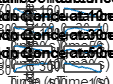

eda_data_filtered = lowpass_filter(EDAD16, sampl_rate, n_order,f_c);
subplot(4,2,8)
plot(TD16,eda_data_filtered)
ylabel('Conductance (uS)')
xlabel('Time (s)')
title('Skin Conductance at 60min')

Filter Function 

function data_filtered = lowpass_filter(data, sampl_rate, n_order,f_c);
[b_low,a_low] = butter(n_order,f_c/sampl_rate,'low');
data_filtered = filtfilt(b_low,a_low,data);
end